# Lab 5

### Actividad 1

% a) Lectura del csv
clear
datos = readtable('COVID.xlsx', 'Sheet', 'Hoja1');

x = datos.dia;
y = datos.N_CASOS;

% b) definir A
A = ones(length(x), 2);
A(:,1) = x;

% c) definir b
b = y;

% d) obtener x_star e y_star
x_star = inv(A' * A) * A' * y;
a_star = x_star(1);
b_star = x_star(2);

y_star = A * x_star;

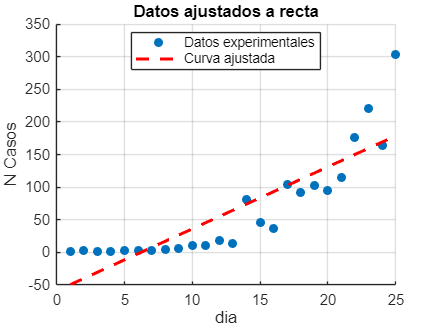

% e) grafico

y_ajustada = a_star * x + b_star;

figure
scatter(x,y, "filled" )
grid on

hold on

plot(x, y_ajustada, '--r', 'LineWidth', 2)

title("Datos ajustados a recta")
xlabel("dia")
ylabel("N Casos")
legend("Datos experimentales", "Curva ajustada", 'Location', 'best')
hold off

#### Es un buen modelo lineal?

No parece que una recta sea la función que mejor se ajuste a los datos.

### Actividad 2

% a) definir y2
y2 = log(y);

% b) encontrar parametros
x2_star = inv(A' * A) * A' * y2;

% c) despejar d
d = exp(x2_star(2));

% d) despejar c
c = x2_star(1);

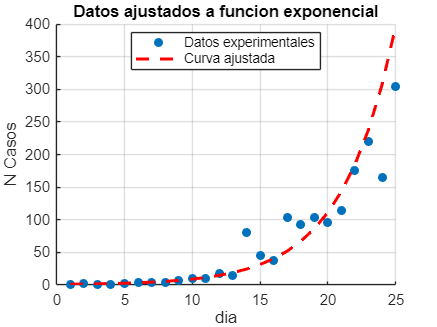

% e) grafico

y2_ajustada = d * exp(c * x);

figure
scatter(x,y, "filled" )
grid on

hold on

plot(x, y2_ajustada, '--r', 'LineWidth', 2)

title("Datos ajustados a funcion exponencial")
xlabel("dia")
ylabel("N Casos")
legend("Datos experimentales", "Curva ajustada", 'Location', 'best')
hold off